1) Retrieve and plot system data

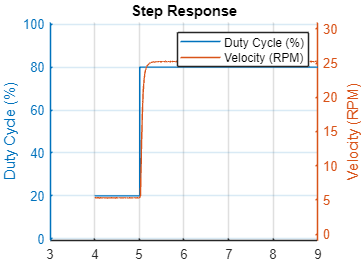

% Import data from Excel file
% Home -> Import Data -> Select Data Excel File -> Import Selection
% VVV Change variable below VVV
file_name = data5;

timestamp = file_name.Timestampms ./ 1000;
duty_cycle = file_name.DutyCycle;
velocity = file_name.VelocityEMARPM;

hold on
yyaxis left;
plot(timestamp, duty_cycle .* 100)
ylabel('Duty Cycle (%)');
ylim([-1, 101])

yyaxis right;
plot(timestamp, velocity)
ylabel('Velocity (RPM)')
ylim([-1, 31])

title('Step Response')
legend('Duty Cycle (%)','Velocity (RPM)')
grid on
hold off

2) Estimate first order system with deadtime

RPM_dev = max(velocity) - median(velocity);

RPM_0 = min(velocity);
RPM_SS = median(velocity) - RPM_dev;
RPM_28 = (RPM_SS - RPM_0) * 0.28 + RPM_0;
RPM_63 = (RPM_SS - RPM_0) * 0.632 + RPM_0;

% Removes duplicate velocities from array
% (Allows interpolation)
map = false(size(velocity));
for i = 1:length(velocity)
    if any(velocity(1:i-1) == velocity(i))
        map(i) = true;
    end
end
timestamp = timestamp(~map);
duty_cycle = duty_cycle(~map);
velocity = velocity(~map);

step_index = find(diff(duty_cycle) ~= 0) + 1;

t_0 = timestamp(step_index);
t_SS = interp1(velocity, timestamp, RPM_SS, 'linear');
t_28 = interp1(velocity, timestamp, RPM_28, 'linear');
t_63 = interp1(velocity, timestamp, RPM_63, 'linear');

K_p = (RPM_SS - RPM_0) / (max(duty_cycle) - min(duty_cycle))

K_p = 33.0638

t = 1.49 * (t_63 - t_28)

t = 0.0378

t_d = t_63 - t - t_0

t_d = 0.0103

3) Tune PI controller

num = [K_p];
den = [t 1];
sys = tf(num, den, 'InputDelay', t_d)

sys =
 
                       33.06
  exp(-0.0103*s) * -------------
                   0.03779 s + 1
 
Continuous-time transfer function.
Model Properties


sys =
 
                       33.02
  exp(-0.0108*s) * -------------
                   0.03902 s + 1
 
Continuous-time transfer function.
Model Properties



tuner = pidTuner(sys, 'PID');